## Week 5 Workshop: Getting to know the data

The goal of this workshop is to load up one of the sample data sets and get to know the data structure and play around with plotting some figures from it. First, dowlowad the sample data set from Moodle, then navigate to the place on your computer where you've saved the data. Then you can load it up:

load rr.utimages.export.mat

The name of the file has the subject ID ('`rr`') the name of the task ('`utimages`', short for 'University of Texas', where this data set came from). The `export` refers to the fac that I've previously loaded the raw data from the experiments, combined all of your experimental files and saved out the variables that I think are relevant to make it easier for you to work with. 

Once you've loaded the mat file, you should have a variable in your workspace called '`data`.' `data` is a structure variable, which means there are lots of types of data stored in different fields. if you type '`data`' int he command window, you can see the first field is the subject name. If you look within that field:

data.rr

ans = struct with fields:
       eyetrace: [1×1 struct]
       saccades: [1×493 struct]
      fixations: [1×493 struct]
         imgkey: {1×493 cell}
         images: [192×1080×1920 double]
    image_index: [493×1 double]
     screeninfo: [1×1 struct]


you can see there's a lot of data relevant to the task. In this workshop we're going to be working through the data and looking getting you familiar with the features, so that next time you're ready to dive into your own data set and start doing some analyses.

### Plotting the eye traces

The first field is '`eyetrace`'. `eyetrace` containes two fields, 'X' and 'Y' that are each [493×4000 double]. This means they contain a matrix with 493 rows adn 4000 columns. In MATLAB, a `double` refers to a data type that represents double-precision floating-point numbers. Double-precision means that each number is represented using 64 bits, consisting of a sign bit, an 11-bit exponent, and a 52-bit fraction (also known as the mantissa or significand). This allows for a wide range of values to be represented with high precision.

In our case, the 493 refers to the number of trials the subject completed. Each image was presented for 4 seconds, so the 4000 is the time at each point in the trial in miliseconds. X and Y refer to the X and Y coordinates of the eye position. 

We can have a look at what the 100th trial looks like:

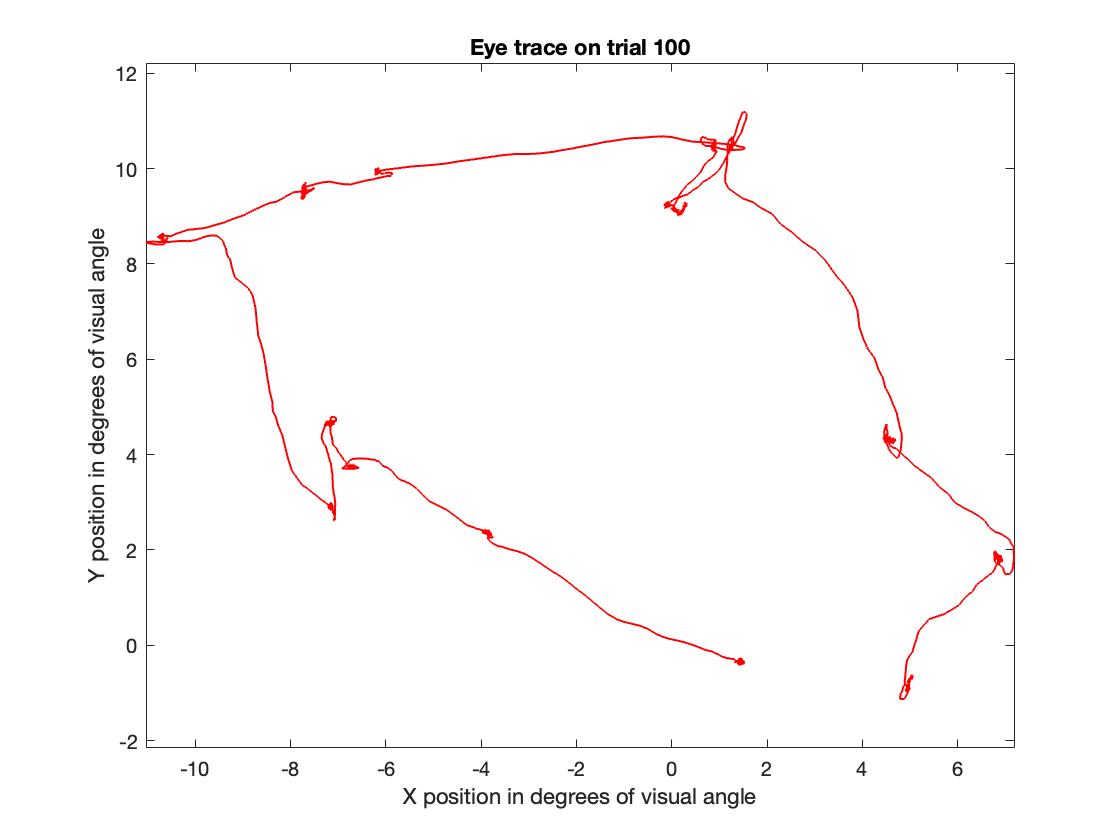

figure;
plot(data.rr.eyetrace.X(100,:),data.rr.eyetrace.Y(100,:),'Color', [1 0 0],'LineWidth',1)
title('Eye trace on trial 100')
xlabel('X position in degrees of visual angle')
ylabel('Y position in degrees of visual angle')
axis equal

This is the X and Y positon of the eye across the trials. You can see little dots where the eye lingered on a certain spot, these are the fixation points. The eye traces in between fixations are the saccades. The fixation and saccade data has already been extracted and saved out for you. We can see what this looks like:

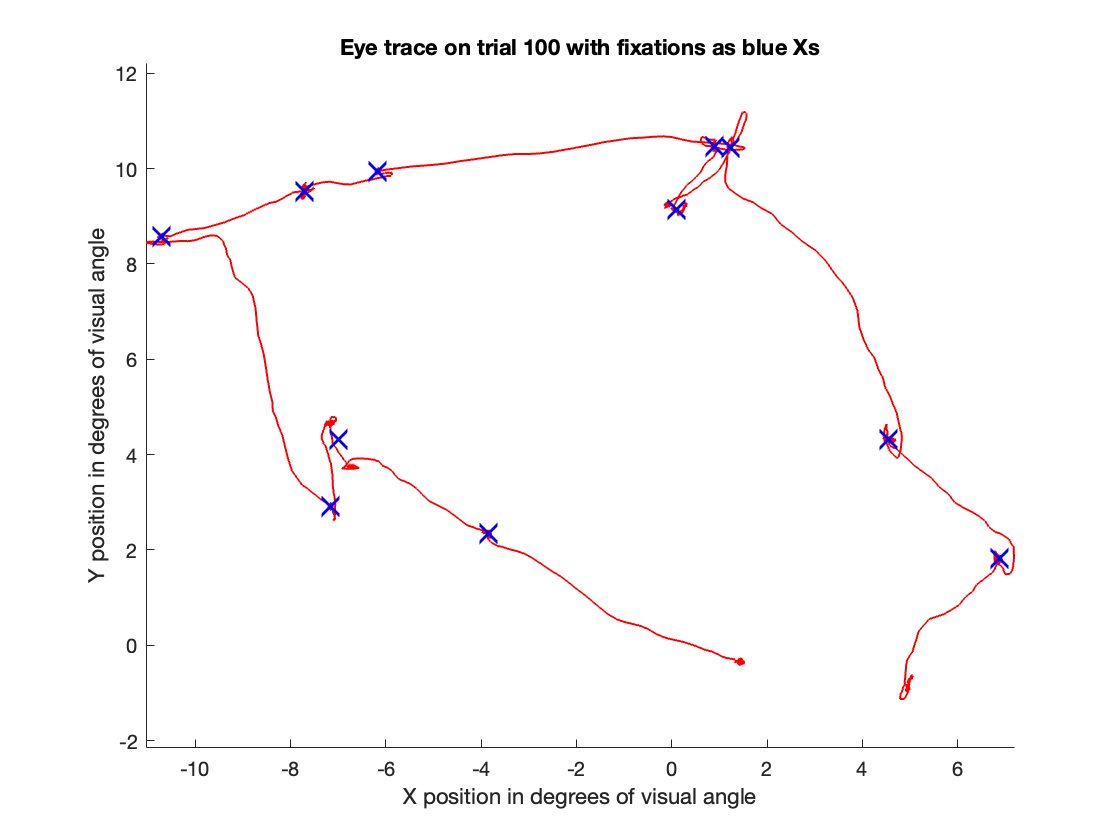

figure;
hold on; % this holds on to the current axes so you can keep adding data to your plots
plot(data.rr.eyetrace.X(100,:),data.rr.eyetrace.Y(100,:),'Color', [1 0 0],'LineWidth',1)
plot(data.rr.fixations(100).fixXY(1,:),data.rr.fixations(100).fixXY(2,:),'x','Color',[0 0 1],'MarkerSize',12,'Linewidth',2)
title('Eye trace on trial 100 with fixations as blue Xs')
xlabel('X position in degrees of visual angle')
ylabel('Y position in degrees of visual angle')
axis equal

Looks like we're doing a pretty good job capturing the fixation points. Now let's try to figure out what imaging we're lookign at.

### Plotting the images

The images are very big - so instead of giving a copy of each image on each trial, your data will include one copy of each unique image.  `data.rr.images `contains these images. You can see for this subject that field is [192×1080×1920 double]. That means there were 192 unique images, and the screen resolution (in pixels) is 1080x1920. So we can't just look at the 100th entry because its not matched to the numer of trials. To figure out which image was shown on each trial, we have a field called `data.rr.image_index: [493×1 double`]. The image index tells us which image was shown on each trial. There's also a field `data.rr.imgkey. `This one is a cell array {1×493 cell}. Each entry of this matrix is the file name for the image shown on each trial. This will be handy when we start combining data across subjects to match up images. But for now, we can figure out which image was shown on trial 100 like this:

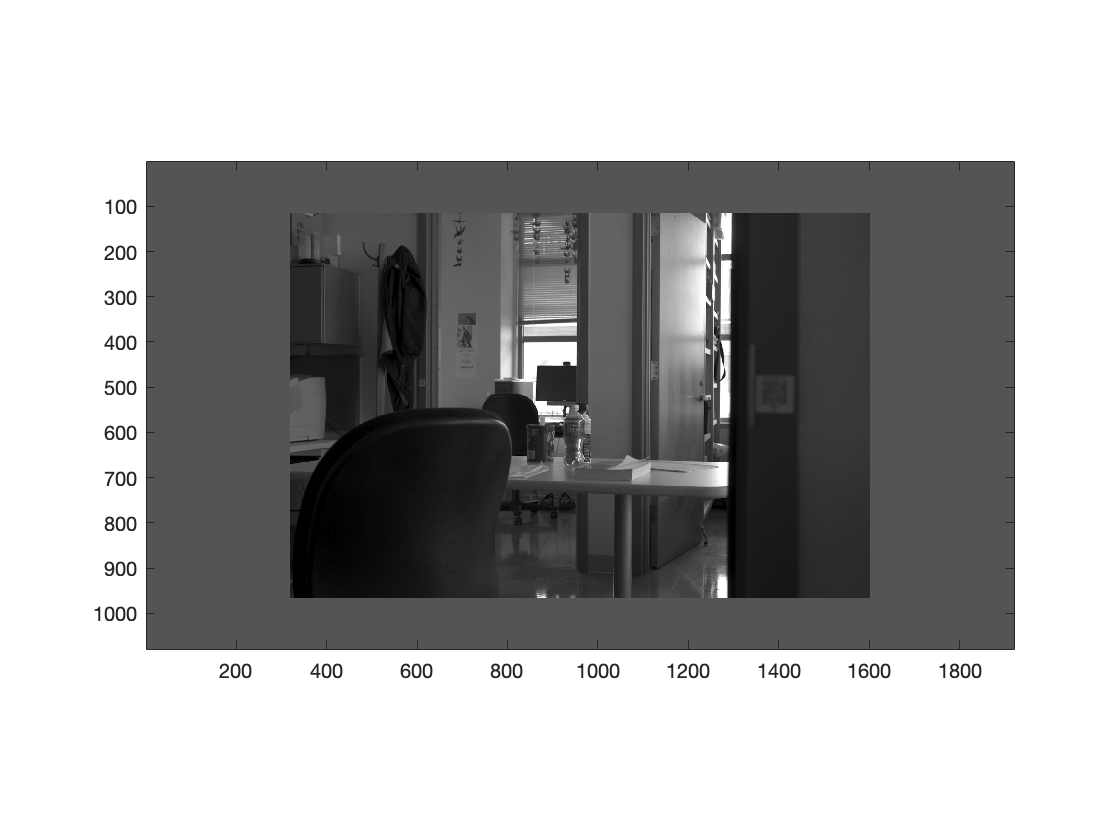

tr100 = data.rr.image_index(100); % find the id number of the image on trial 100
img = squeeze(data.rr.images(tr100,:,:));
figure; 
imagesc(img) % this is the image that was shown
axis equal
axis tight
colormap('gray'); % matlab doesnt know the image was in black and white. this tells it to plot in greyscale.

 Great! now we know what image was shown and what the eye data looked like, next step is to put them together! 

### Putting it all together

This gets a bit trickier than it sounds because the two data sets are in different units. The eye trace is in what we call degrees of visual angle. The image, as we said above, is in pixels. So we need to convert degrees of visual angle to pixels per degree.

Luckily, we've saved information about the size of the screen in degrees of visual angle so we can do the math. 

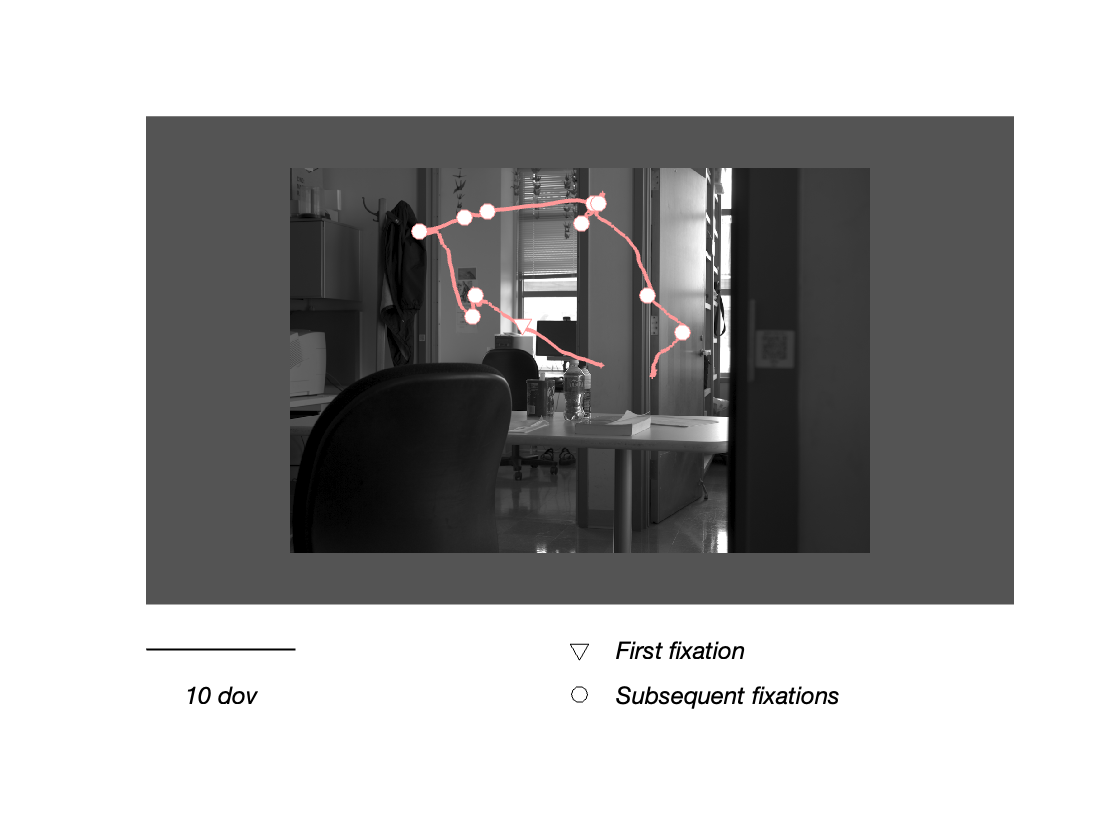

width = data.rr.screeninfo.dov_width; % width of the screen in degrees of visual angle

pixelsperdeg = data.rr.screeninfo.xpixels/width;
pixelxzero = data.rr.screeninfo.xpixels/2; % find the center of the screen x coordinate
pixelyzero = data.rr.screeninfo.ypixels/2; % find the center of the screen y coordinate

figure;

trialnumber = 100;

% convert x and y traces from dov into pixels
xtrace = data.rr.eyetrace.X(trialnumber,:) .* pixelsperdeg + pixelxzero;
ytrace = data.rr.eyetrace.Y(trialnumber,:) .* -pixelsperdeg + pixelyzero;

% lets find the first fixation
firstfix_x = data.rr.fixations(trialnumber).fixXY(1,1) .* pixelsperdeg + pixelxzero;
firstfix_y = data.rr.fixations(trialnumber).fixXY(2,1) .* -pixelsperdeg + pixelyzero;

% all the other fixations
fix_x = data.rr.fixations(trialnumber).fixXY(1,2:end) .* pixelsperdeg + pixelxzero;
fix_y = data.rr.fixations(trialnumber).fixXY(2,2:end) .* -pixelsperdeg + pixelyzero;

% now get the image
trind = data.rr.image_index(trialnumber); % find the id number of the image on trial 100
img = squeeze(data.rr.images(trind,:,:));

% now we can plot it all!
figure;
imagesc(img)
colormap('gray')
hold on;

plot(xtrace,ytrace,'-', 'Color', '#FF9999','LineWidth',2) % you can also specifiy color with hex values!
plot(firstfix_x, firstfix_y,'v','Color','#FF9999','MarkerFaceColor',[1 1 1],'MarkerSize',8)
plot(fix_x, fix_y,'o','Color','#FF9999','MarkerFaceColor',[1 1 1],'MarkerSize',8)

% legends (matlab has built in fucntions, or you can write your own!)
plot(pixelxzero, data.rr.screeninfo.ypixels+100,'v','Color','k','MarkerFaceColor',[1 1 1],'MarkerSize',8)
text(pixelxzero + 80, data.rr.screeninfo.ypixels+100,'First fixation','FontName','Helvetica', 'FontAngle','italic','FontSize',12,'HorizontalAlignment','left');
plot(pixelxzero, data.rr.screeninfo.ypixels+200,'o','Color','k','MarkerFaceColor',[1 1 1],'MarkerSize',8)
text(pixelxzero + 80, data.rr.screeninfo.ypixels+200,'Subsequent fixations','FontName','Helvetica', 'FontAngle','italic','FontSize',12,'HorizontalAlignment','left');

% its always a good idea to plot a scale bar
scalebar = pixelsperdeg*10;
line([1 scalebar], [data.rr.screeninfo.ypixels+100 data.rr.screeninfo.ypixels+100],'Color',[0 0 0],'Linewidth',1)
text(mean([1 scalebar]), data.rr.screeninfo.ypixels+200,'10 dov','FontName','Helvetica', 'FontAngle','italic','FontSize',12,'HorizontalAlignment','center');

axis equal
axis off

### Exercises

Now with your groups, here are some exercises to try and answer:

- How many trials total were there for this image?

- How many trials were there for each of the 192 images? Can you plot this as a bar chart or histogram?

- For all of the trials where this image was shown, can you plot all of the eye traces over it? Maybe in different colors?

- What was the average number of fixations per image? How does this image compare?

### Other notes on making plots in matlab:

#### Principles for plotting figures

These things may seem intuitive, but they're the most common mistakes I see when watching student presentations or reading a thesis. Figures are the way we communicate our data to an audience. Just like clear and concise writing, it is imperiative that your figures are legible and easy to understand. Your reader/viewer does not have as much insight into your data as you do, and they need to be able to digest your findings quickly and easily. No one is going to spend hours pouring over each figure in your thesis/grant/presnentation/manuscript. If they can't figure it out quickly, they'll most likely get frustrated and disregard it. As much as the text you write, the figures are telling the story of your results.

- **Always label your axes. **This seems obvious, but it is amazing how often it's missed. Every axis needs to be properly labeled - with units. After you've labeled your axes - double-check the labels to make sure they're correct. Again - seems obvious - but you'd be surprised.

- **Choose legible fonts/data markers. **There is no point in labeling your axes if the text is so small no one can read it. Choose sans serif fonts (unless required to use Times New Roman). Minimum san serif font sizes should be 10 for figures in text (manuscripts/grants) and 28 for presentations (posters/talks). If you're required to use Times New Roman - up it to 12 and 30 repsectively. And that's the *minimum*, important headings/text should be larger (particularly in presentations). Same goes for the data itself, chose line widths and marker sizes that are legible so that people can see the data. Typically, in maltab, the line width of the axes are 0.5, so if you're adding extra axes (i.e. a unity line), this is what you should use. Data should be plotted at a line width 1 or more to stand out. Marker size varies depending on the size of the panel and number of data points, so you probalby have to play around a bit to see what will be legible.

- **Color should be used to convey specific information.** Using color can be very helpful - but only if it conveys specific information about the data. Avoid using color gratuitously. Unnecessary color is distracting and confusing to the reader. Colors should convey specific information about the data and be used consistently throughout the document/presnetatation. For example, if you use 'red' to indicate 'direction selective cells' and 'blue' to indicate 'non-direction selective cells' this shoudl be consistent in every figure. And, critically, red and blue should not be used for anything else in the document/presentation. Also, because color is conveying information the colors should be *accessible* to all readers, regardless of visual ability. More on this below, with resources for color-blind friendly color schemes.

#### Resources for using color 

#### Accessibility

Whenever possible, choose colors that are accessible to people of all visual abilities. This is not as simple as avoiding the well known 'bad' combinations like red-green and blue-green. Here are some good resources for choosing accessible color schemes:

- [https://colorbrewer2.org/](https://colorbrewer2.org/) - helps craft color schemes/palletes. Make sure you select 'Colorblind safe'

- [https://colororacle.org/](https://colororacle.org/) - free color blindness simulator - will temporarily render your computer screen as it would be seen by people of different visual abilities. great for checking your figures.

#### Color maps

The matlab color maps are all awful. Choose a color scale that is perceptually uniform - meaning the increments between colors are are uniform in contrast to more accurately represent your data. In general, these maps are also more colorblind-friendly, but you can find maps that are specifically designed to be accessible as well. Circular maps (for plotting angular data) are particularly difficult for colorblindness - I have not found a great one. But choosing a perceptually uniform one is far superior to one that is not. Here are some places to look:

- [https://colorcet.com/](https://colorcet.com/)

- [https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps](https://www.mathworks.com/matlabcentral/fileexchange/51986-perceptually-uniform-colormaps) 